# Example template

This script is the **pattern** for the example sections that close each chapter. It is not a chapter: it exists to fix one structure so that the examples of the four models stay comparable, and so that the final recap can hold the topology fixed and vary the model.

Every example follows the same seven steps, in the order used in the course labs and in Homework 1:

Step 3 is the only one that differs between models, and that is the point: the topology is shared, the matrix built from it is not.

% Bootstrap: walk up until setup_paths.m is found, then put the library on
% the path. Works from any folder, and from the .m or the generated .mlx.
projectDir = fileparts(mfilename('fullpath'));
while ~isfile(fullfile(projectDir, 'setup_paths.m')) && ...
        ~strcmp(projectDir, fileparts(projectDir))
    projectDir = fileparts(projectDir);
end
addpath(projectDir);
setup_paths;

## Shared setup

One initial condition and one horizon for every example, so that any two figures in the project can be compared directly.

rng(0);
n  = 6;
x0 = rand(n,1)

x0 =     0.8147
    0.9058
    0.1270
    0.9134
    0.6324
    0.0975


x0_mean = mean(x0)

x0_mean = 0.5818


K = 40;                      % discrete-time horizon
t = linspace(0, 15, 300);    % continuous-time grid

## The common topology family

Five topologies on n = 6 nodes, reused by every chapter. They are the ones already used in Homework 1, so the examples connect to work already done.

CONVENTION. A(i,j) > 0 means agent i accords weight to agent j: row i lists whom i listens to. This is the convention of the homework and of the project, so no transpose is ever needed.

TOPOLOGY(name) is a local function at the end of this file. When the chapters adopt this template it should become a single shared file, so that all of them build their examples from the same five matrices. Each example still DISPLAYS the matrix it uses, so the reader always sees it.

for name = ["cycle" "cycle-self" "star" "star-out" "two-blocks"]
    fprintf('%-12s  out-degrees %s\n', name, mat2str(sum(topology(name),2).'));
end

cycle         out-degrees [1 1 1 1 1 1]
cycle-self    out-degrees [2 1 1 1 1 1]
star          out-degrees [5 1 1 1 1 1]
star-out      out-degrees [5 0 0 0 0 0]
two-blocks    out-degrees [2 2 2 2 2 2]


## PART A - one model, several topologies

This is the pattern a chapter uses: the model is fixed, the topology varies.

## A.1 French-DeGroot on the directed cycle

A = topology('cycle');
W = row_stochastic(A)

W =      0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1
     1     0     0     0     0     0


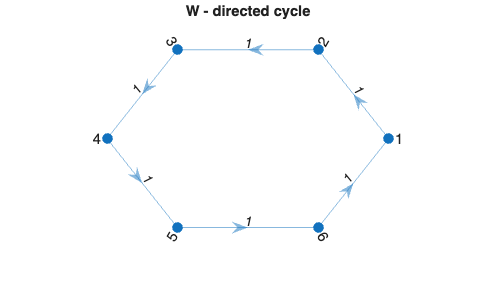


K = 18;                      % a few periods: enough to see the oscillation

show_graph(W, 'W - directed cycle')

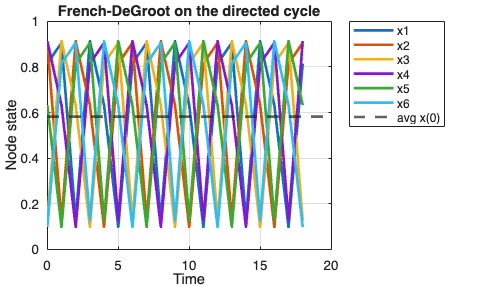

X = sim_degroot(W, x0, K);
show_dynamics(0:K, X, 'French-DeGroot on the directed cycle', x0_mean)

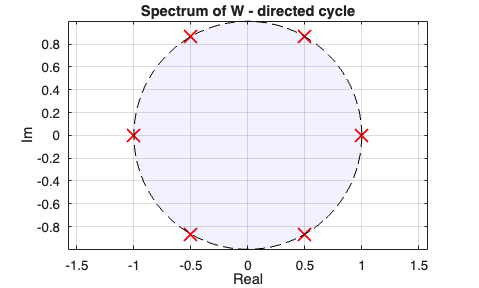

  lambda_1 =  -1.0000  +0.0000i
  lambda_2 =  -0.5000  +0.8660i
  lambda_3 =  -0.5000  -0.8660i
  lambda_4 =   0.5000  +0.8660i
  lambda_5 =   0.5000  -0.8660i
  lambda_6 =   1.0000  +0.0000i


show_spectrum(W, 'discrete', 'Spectrum of W - directed cycle')


report_discrete(W, x0)

  rooted = 1, convergent = 0, consensus = 0
  no limit: a closed component is periodic, opinions oscillate


## A.2 French-DeGroot on the directed cycle with a self-loop

The only change is one entry of A, and it changes everything: the self-loop makes the graph aperiodic, so the model now converges.

A = topology('cycle-self');
W = row_stochastic(A)

W =     0.5000    0.5000         0         0         0         0
         0         0    1.0000         0         0         0
         0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
    1.0000         0         0         0         0         0


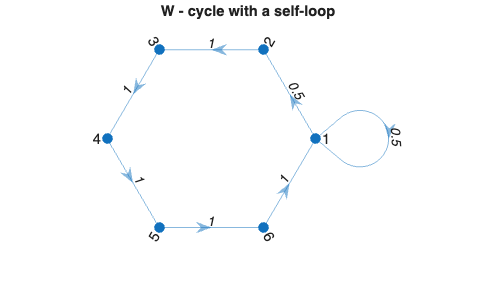


K = 40;

show_graph(W, 'W - cycle with a self-loop')

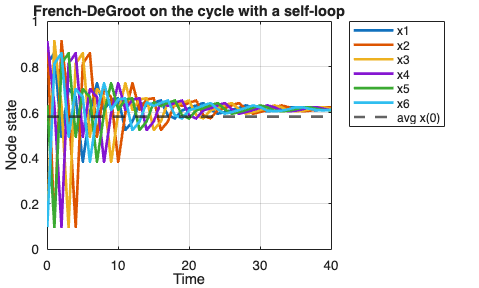

X = sim_degroot(W, x0, K);
show_dynamics(0:K, X, 'French-DeGroot on the cycle with a self-loop', x0_mean)

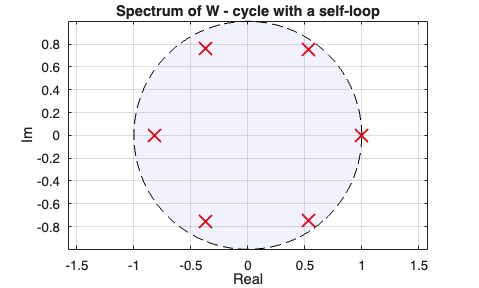

  lambda_1 =   1.0000  +0.0000i
  lambda_2 =   0.5348  +0.7507i
  lambda_3 =   0.5348  -0.7507i
  lambda_4 =  -0.8231  +0.0000i
  lambda_5 =  -0.3733  +0.7587i
  lambda_6 =  -0.3733  -0.7587i


show_spectrum(W, 'discrete', 'Spectrum of W - cycle with a self-loop')


report_discrete(W, x0)

  rooted = 1, convergent = 1, consensus = 1
  x(inf) = [0.6151 0.6151 0.6151 0.6151 0.6151 0.6151]
  spread = 0.0000


## PART B - one topology, several models

This is the pattern the final recap uses: the topology is fixed and the model varies. The topology below is the same directed cycle of A.1.

## B.1 Abelson (continuous time) on the directed cycle

Same graph as A.1, but the raw weights A are used, not the row-stochastic W: in the continuous-time model the row sums are interaction RATES, not shares of a unit budget.

A = topology('cycle');
L = laplacian(A)

L =      1    -1     0     0     0     0
     0     1    -1     0     0     0
     0     0     1    -1     0     0
     0     0     0     1    -1     0
     0     0     0     0     1    -1
    -1     0     0     0     0     1


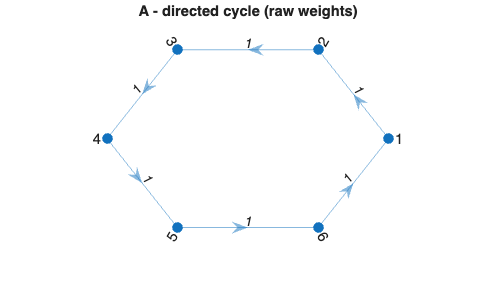


show_graph(A, 'A - directed cycle (raw weights)')

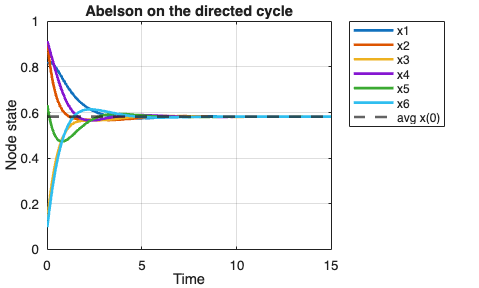

X = sim_abelson(A, x0, t);
show_dynamics(t, X, 'Abelson on the directed cycle', x0_mean)

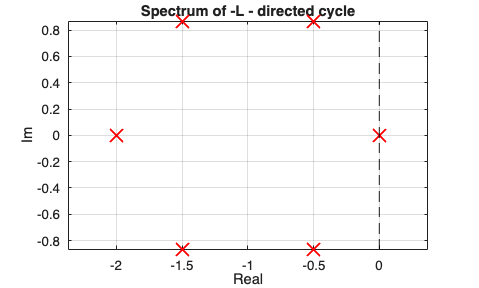

  lambda_1 =  -2.0000  +0.0000i
  lambda_2 =  -1.5000  +0.8660i
  lambda_3 =  -1.5000  -0.8660i
  lambda_4 =  -0.5000  +0.8660i
  lambda_5 =  -0.5000  -0.8660i
  lambda_6 =  -0.0000  +0.0000i


show_spectrum(-L, 'continuous', 'Spectrum of -L - directed cycle')


report_continuous(L, x0)

  w' = [0.1667 0.1667 0.1667 0.1667 0.1667 0.1667]
  x(inf) = 0.5818 (consensus)
  Fiedler-like rate Re(lambda_2) = 0.5000


## B.2 Taylor (continuous time, with prejudices) on the directed cycle

Two ingredients are added to the topology: the prejudice rates gamma and the prejudices u. Everything else is unchanged.

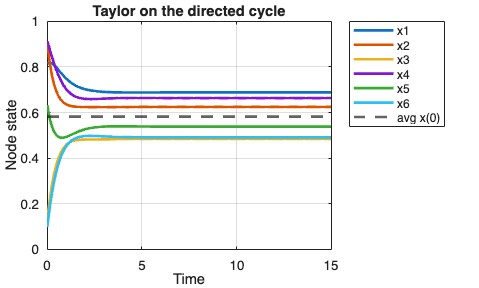

% Uniform anchoring is used here because it is the only choice admissible on
% EVERY topology of the family: the anchor set must reach every agent, and on
% 'star-out' and 'two-blocks' a single anchor at node 1 does not. Check any
% other choice with PREJUDICE_REACH before using it.

A     = topology('cycle');
gamma = 0.5 * ones(n,1);        % every agent anchored, at the same rate
u     = x0;                     % prejudices = initial opinions

X = sim_taylor(A, gamma, u, x0, t);
show_dynamics(t, X, 'Taylor on the directed cycle', x0_mean)

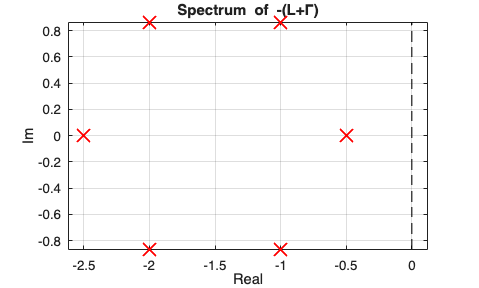

  lambda_1 =  -2.5000  +0.0000i
  lambda_2 =  -2.0000  +0.8660i
  lambda_3 =  -2.0000  -0.8660i
  lambda_4 =  -1.0000  +0.8660i
  lambda_5 =  -1.0000  -0.8660i
  lambda_6 =  -0.5000  +0.0000i


show_spectrum(-(laplacian(A) + diag(gamma)), 'continuous', 'Spectrum of -(L+\Gamma)')


xstar = taylor_equilibrium(A, gamma, u);
fprintf('equilibrium  x* = %s\n', mat2str(round(xstar.',4)));

equilibrium  x* = [0.6882 0.625 0.4846 0.6634 0.5383 0.4913]


fprintf('spread       = %.4f   (0 would mean consensus)\n', max(xstar)-min(xstar));

spread       = 0.2037   (0 would mean consensus)


## B.3 Friedkin-Johnsen (discrete time, with prejudices) on the directed cycle

The discrete-time counterpart of B.2. Note that the periodicity that stops French-DeGroot in A.1 no longer prevents convergence: anchoring pulls every eigenvalue of Lambda*W strictly inside the unit circle.

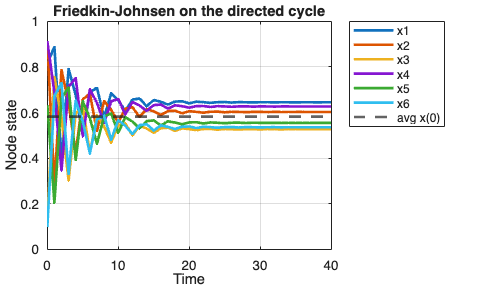

A      = topology('cycle');
W      = row_stochastic(A);
lambda = 0.8 * ones(n,1);       % susceptibility, same for every agent
u      = x0;

X = sim_friedkin_johnsen(W, lambda, u, x0, K);
show_dynamics(0:K, X, 'Friedkin-Johnsen on the directed cycle', x0_mean)

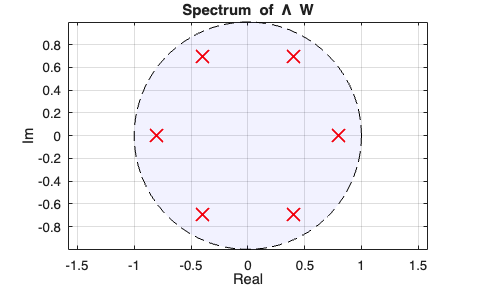

  lambda_1 =  -0.8000  +0.0000i
  lambda_2 =  -0.4000  +0.6928i
  lambda_3 =  -0.4000  -0.6928i
  lambda_4 =   0.4000  +0.6928i
  lambda_5 =   0.4000  -0.6928i
  lambda_6 =   0.8000  +0.0000i


show_spectrum(diag(lambda)*W, 'discrete', 'Spectrum of \Lambda W')


xinf = fj_equilibrium(W, lambda, u);
fprintf('equilibrium  x(inf) = %s\n', mat2str(round(xinf.',4)));

equilibrium  x(inf) = [0.6449 0.6025 0.5266 0.6265 0.5548 0.5354]


fprintf('rho(Lambda W)       = %.4f   (< 1 means exponentially stable)\n', ...
        max(abs(eig(diag(lambda)*W))));

rho(Lambda W)       = 0.8000   (< 1 means exponentially stable)


fprintf('spread              = %.4f\n', max(xinf)-min(xinf));

spread              = 0.1183


## PART C - the one topology that needs an adaptation

On 'star-out' the hub listens to all the leaves and the leaves listen to nobody, so their out-degrees are zero and D_out cannot be inverted: the row-stochastic matrix is undefined. This is the situation of HW Ex.4, point 2, and the course fix is the Perron matrix

The continuous-time models are unaffected, because they never invert D_out. For Taylor and Friedkin-Johnsen this topology also constrains the anchors: the leaves listen to nobody, so only an anchor set containing all of them reaches the whole graph.

A = topology('star-out');
dout = sum(A,2).'

dout =      5     0     0     0     0     0



eps = 1 / max(sum(A,2));
P   = eye(n) - eps * laplacian(A)

P =          0    0.2000    0.2000    0.2000    0.2000    0.2000
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0         0
         0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000


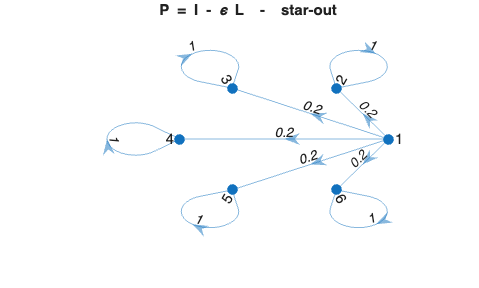


show_graph(P, 'P = I - \epsilon L  -  star-out')

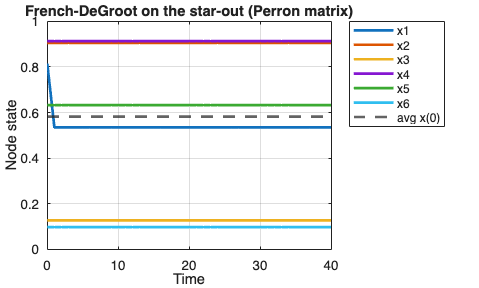

X = sim_degroot(P, x0, K);
show_dynamics(0:K, X, 'French-DeGroot on the star-out (Perron matrix)', x0_mean)

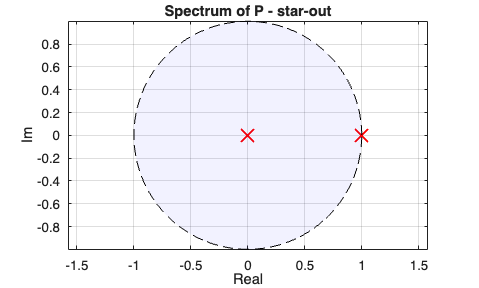

  lambda_1 =   0.0000  +0.0000i
  lambda_2 =   1.0000  +0.0000i
  lambda_3 =   1.0000  +0.0000i
  lambda_4 =   1.0000  +0.0000i
  lambda_5 =   1.0000  +0.0000i
  lambda_6 =   1.0000  +0.0000i


show_spectrum(P, 'discrete', 'Spectrum of P - star-out')


report_discrete(P, x0)

  rooted = 0, convergent = 1, consensus = 0
  x(inf) = [0.5352 0.9058 0.127 0.9134 0.6324 0.0975]
  spread = 0.8158


## PART D - cross-model recap

The table the project is building towards: topology fixed on each row, one column per model. It uses no plotting, so adding a topology or a model is one line.

models     = {'French-DeGroot','Abelson','Taylor','Friedkin-Johnsen'};
topologies = {'cycle','cycle-self','star','star-out','two-blocks'};

spread = zeros(numel(topologies), numel(models));
for i = 1:numel(topologies)
    A = topology(topologies{i});
    tt = linspace(0, 120, 201);
    spread(i,1) = final_spread(sim_degroot(dt_matrix(A), x0, 400));
    spread(i,2) = final_spread(sim_abelson(A, x0, tt));
    spread(i,3) = final_spread(sim_taylor(A, 0.5*ones(n,1), x0, x0, tt));
    spread(i,4) = final_spread(sim_friedkin_johnsen(dt_matrix(A), 0.8*ones(n,1), x0, x0, 400));
end

recap = array2table(round(spread,4), 'VariableNames', models, 'RowNames', topologies)

recap = 5×4 table
                  French-DeGroot    Abelson    Taylor    Friedkin-Johnsen
                  ______________    _______    ______    ________________

    cycle                NaN             0     0.2037         0.1183     
    cycle-self             0             0     0.2037         0.1397     
    star                 NaN             0     0.2719         0.1632     
    star-out          0.8158        0.8158     0.8158         0.8158     
    two-blocks        0.0681        0.0681     0.1738         0.1738     



% A spread of 0 is consensus, anything else is persistent disagreement, and
% NaN marks a model that never settles. Four things the table already shows:
%
%   * 'cycle' and 'star' are periodic, so French-DeGroot oscillates (NaN)
%     while Abelson, on the same graph, converges. Periodicity is an artefact
%     of synchronous discrete updating.
%   * on 'cycle' the same anchoring that makes Taylor and FJ disagree also
%     makes FJ CONVERGE where French-DeGroot could not: anchoring pulls every
%     eigenvalue of Lambda*W strictly inside the unit circle.
%   * 'cycle' and 'cycle-self' give Taylor the same number. A self-loop adds
%     equally to the degree and to A, so it CANCELS in L = diag(A*1) - A: the
%     continuous-time models cannot see it, while for the discrete-time ones
%     it is exactly what turns period 6 into period 1.
%   * on 'two-blocks' the averaging models disagree because the graph is cut
%     in two (0.068, two values), the anchored models because every agent
%     keeps its own prejudice (0.174, six values). Same symptom, different
%     mechanism.
%
% Taylor and FJ coincide on 'two-blocks' only because the parameters happen to
% match there: the two models give the same equilibrium when
% lambda_i = d_i / (d_i + gamma_i), and d = 2 makes gamma = 0.5 match lambda = 0.8.

## Local functions

Three figure helpers and two report helpers, written once and reused by every example above. They are deliberately short: if they grow, the example stops being readable as a mathematical statement.

function A = topology(name)
%TOPOLOGY The common family of test graphs, n = 6.
switch name
    case 'cycle'                       % directed ring
        A = diag(ones(5,1),1); A(6,1) = 1;
    case 'cycle-self'                  % directed ring + one self-loop
        A = diag(ones(5,1),1); A(6,1) = 1; A(1,1) = 1;
    case 'star'                        % bidirectional star, hub = 1
        A = zeros(6); A(1,2:6) = 1; A(2:6,1) = 1;
    case 'star-out'                    % hub listens to all the leaves
        A = zeros(6); A(1,2:6) = 1;
    case 'two-blocks'                  % two disjoint triangles
        A = blkdiag(ones(3)-eye(3), ones(3)-eye(3));
    otherwise
        error('unknown topology "%s"', name);
end
end

function W = dt_matrix(A)
%DT_MATRIX Row-stochastic matrix of A, or the Perron matrix when D_out is singular.
if any(sum(A,2) == 0)
    W = eye(size(A,1)) - (1/max(sum(A,2))) * laplacian(A);
else
    W = row_stochastic(A);
end
end

function show_graph(A, name)
%SHOW_GRAPH Draw the digraph with its numeric weights on the edges.
figure;
G = digraph(A);
p = plot(G, 'Layout', 'circle');
p.EdgeLabel  = round(G.Edges.Weight, 3);
p.MarkerSize = 7;  p.ArrowSize = 12;  p.NodeFontSize = 11;
title(name); axis off
end

function show_dynamics(tk, X, name, ref)
%SHOW_DYNAMICS Trajectories against time, with the mean of x(0) as reference.
figure;
plot(tk, X', 'LineWidth', 2); hold on
yline(ref, '--', 'LineWidth', 2); hold off
grid on; title(name); xlabel('Time'); ylabel('Node state')
legend([compose("x%d", 1:size(X,1)), "avg x(0)"], 'Location', 'northeastoutside')
end

function show_spectrum(M, domain, name)
%SHOW_SPECTRUM Eigenvalues against the stability boundary, and their list.
figure;
ev = eig(M);
plot(real(ev), imag(ev), 'rx', 'MarkerSize', 14, 'LineWidth', 1.5); hold on
if strcmp(domain, 'discrete')
    th = linspace(0, 2*pi, 200);
    fill(cos(th), sin(th), 'b', 'FaceAlpha', 0.05, ...
         'EdgeColor', 'k', 'LineStyle', '--');
else
    xline(0, 'k--', 'LineWidth', 1);
end
hold off; grid on; axis equal
title(name); xlabel('Real'); ylabel('Im')
for i = 1:numel(ev)
    fprintf('  lambda_%d = %8.4f %+8.4fi\n', i, real(ev(i)), imag(ev(i)));
end
end

function report_discrete(W, x0)
%REPORT_DISCRETE The quantities a discrete-time example should state.
s = graph_summary(W);
fprintf('  rooted = %d, convergent = %d, consensus = %d\n', ...
        s.rooted, s.convergent, s.consensus);
try
    xinf = limit_matrix(W) * x0;
    fprintf('  x(inf) = %s\n', mat2str(round(xinf.',4)));
    fprintf('  spread = %.4f\n', max(xinf) - min(xinf));
catch
    fprintf('  no limit: a closed component is periodic, opinions oscillate\n');
end
end

function report_continuous(L, x0)
%REPORT_CONTINUOUS The quantities a continuous-time example should state.
w = null(L.');
if size(w,2) == 1
    w = w / sum(w);
    fprintf('  w'' = %s\n', mat2str(round(w.',4)));
    fprintf('  x(inf) = %.4f (consensus)\n', w.' * x0);
else
    fprintf('  ker(L'') has dimension %d: no consensus, block agreement\n', size(w,2));
end
re = sort(real(eig(L)));
fprintf('  Fiedler-like rate Re(lambda_2) = %.4f\n', re(2));
end

function s = final_spread(X)
%FINAL_SPREAD Disagreement left at the end of a run; NaN if it did not settle.
% Two checks are needed. The consecutive-sample test catches oscillation of
% any period; the long-range test catches a run that is still drifting.
K = size(X,2);
moved_recently = max(abs(X(:,end) - X(:,end-1)));
moved_overall  = max(abs(X(:,end) - X(:,max(1, K - round(0.2*K)))));
if max(moved_recently, moved_overall) > 1e-6
    s = NaN;                       % not settled
else
    s = max(X(:,end)) - min(X(:,end));
end
end